w=[4 -2];
b=-3;

%activation function
func='tansig';

%define input vector
v=[2 3];

% Calculate neuron output
activatio_potential=v*w'+b;
neuron_output=feval(func,activatio_potential) 

neuron_output = -0.7616

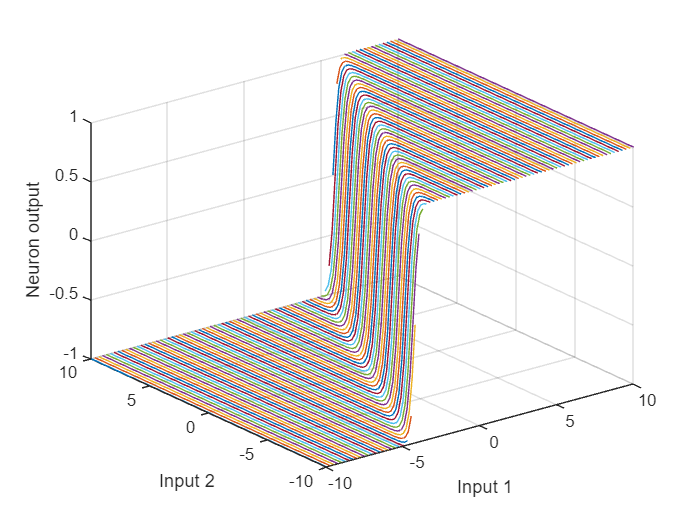


% Plot neuron output over the range of inputs
[p1,p2]=meshgrid(-10:.25:10);
z=feval(func, [p1(:) p2(:)] * w' + b);
z=reshape(z,length(p1),length(p2));
plot3(p1,p2,z)
grid on
xlabel('Input 1')
ylabel('Input 2')
zlabel('Neuron output')